This is Code for Running Convolution Code for a single input sequence with Hard Decoding.

noOfInput=1;
lenOfInput=8;
noOfState=8;
lenOfOutput=2;
maxV=1;
rate=noOfInput/lenOfOutput;
sLog=linspace(4,7,7);% value of Eb/N0 in db
s=10.^(sLog/10);% value of Eb/N0 in normal scale
g=2*rate.*s;% value of Es/No in normal scale
Diagram=stateDiagram(noOfState,noOfInput);
Pow=4;
S=1/sqrt(g(Pow));
input=randi([0,1],1,lenOfInput-log2(noOfState));
zeroPadd=zeros(1,log2(noOfState));
input=[input,zeroPadd]

input =      1     1     0     1     1     0     0     0


output=[];
prevState=zeros(1,log2(noOfState));
for i=1:lenOfInput/noOfInput
    [out,prevState]=Encoder(input((i-1)*noOfInput+1:i*noOfInput),prevState);
    output=[output,out];
end
output

output =      1     0     0     1     0     0     0     1     0     1     0     0     1     1     0     0


send=BPSKSender(output,maxV);
send=AWGNChannel(send,S);
receive=BPSKHardReceiver(send);
decoded=decoderHard(receive,lenOfOutput,noOfState,Diagram)

decoded =      1     1     0     1     1     0     0     0


BER=sum(xor(input,decoded))/lenOfInput

BER = 0

This is Code for Running Convolution Code for a single input sequence with Soft Decoding.

noOfInput=1;
lenOfInput=8;
noOfState=8;
lenOfOutput=2;
maxV=1;
noOfBand=8;
rate=noOfInput/lenOfOutput;
sLog=linspace(4,7,7);% value of Eb/N0 in db
s=10.^(sLog/10);% value of Eb/N0 in normal scale
g=2*rate.*s;% value of Es/No in normal scale
Diagram=stateDiagram(noOfState,noOfInput);
Pow=4;
S=1/sqrt(g(Pow));
input=randi([0,1],1,lenOfInput-log2(noOfState));
zeroPadd=zeros(1,log2(noOfState));
input=[input,zeroPadd]

input =      0     1     1     1     1     0     0     0


output=[];
prevState=zeros(1,log2(noOfState));
for i=1:lenOfInput/noOfInput
    [out,prevState]=Encoder(input((i-1)*noOfInput+1:i*noOfInput),prevState);
    output=[output,out];
end
output

output =      0     0     1     0     0     1     1     0     1     0     0     0     1     1     0     0


send=BPSKSender(output,maxV);
send=AWGNChannel(send,S);
comp=zeros(size(send));
receive=BPSKSoftReceiver(send,noOfBand,maxV,S);
decoded=decoderSoft(receive,lenOfOutput,noOfState,Diagram,noOfBand,1)% 1 means Euclid Distance 0 means manhattan Distance

decoded =      0     1     1     1     1     0     0     0


BER=sum(xor(input,decoded))/lenOfInput

BER = 0

This is Code for running Monte Carlo Simulation on Hard and Soft Convolution Code.

Output is a Graph for BER(Bit Error Rate) and PER (Probablity of error in decoding)

Input is the energy of noise, size of Encoder and length of input. 

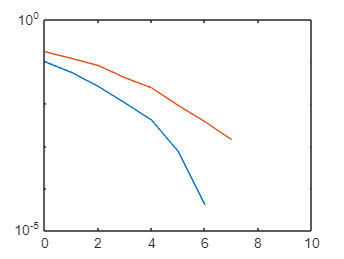

noOfInput=1;%To select the size of encoder
lenOfInput=50;
noOfState=8;%To select the size of encoder 
lenOfOutput=2;
maxV=1;
noOfBand=8;
rate=noOfInput/lenOfOutput;
sLog=linspace(0,10,11);% value of Eb/N0 in db
s=10.^(sLog/10);% value of Eb/N0 in normal scale
g=s;% value of Es/No in normal scale
Diagram=stateDiagram(noOfState,noOfInput);
nMax=1000;
BERS=zeros(1,11);
BERH=zeros(1,11);
PerrDecSoft=zeros(1,11);
PerrDecHard=zeros(1,11);
inputSet=zeros(nMax,lenOfInput-log2(noOfState));
for i=1:nMax
    inputSet(i,:)=randi([0,1],1,lenOfInput-log2(noOfState));
end
for Pow=1:11
    S=1/sqrt(g(Pow));
    for iter=1:nMax
        input=inputSet(iter,:);
        zeroPadd=zeros(1,log2(noOfState));
        input=[input,zeroPadd];
        output=[];
        prevState=zeros(1,log2(noOfState));
        for i=1:lenOfInput/noOfInput
            [out,prevState]=Encoder(input((i-1)*noOfInput+1:i*noOfInput),prevState);
            output=[output,out];
        end
        send=BPSKSender(output,maxV);
        send=AWGNChannel(send,S);
        receive=BPSKSoftReceiver(send,noOfBand,maxV,S);
        receive1=BPSKHardReceiver(send);
        decoded=decoderSoft(receive,lenOfOutput,noOfState,Diagram,noOfBand,1);% Euclid Distance
        decoded1=decoderHard(receive1,lenOfOutput,noOfState,Diagram);
        BERS(Pow)=BERS(Pow)+sum(xor(input(1:end-log2(noOfState)),decoded(1:end-log2(noOfState))));
        BERH(Pow)=BERH(Pow)+sum(xor(input(1:end-log2(noOfState)),decoded1(1:end-log2(noOfState))));
        % We dont need to know what the last 3 bits are since they will be 0
        if(~isequal(input(1:end-log2(noOfState)),decoded(1:end-log2(noOfState))))
            PerrDecSoft(Pow)=PerrDecSoft(Pow)+1;
        end
        if(~isequal(input(1:end-log2(noOfState)),decoded1(1:end-log2(noOfState))))
            PerrDecHard(Pow)=PerrDecHard(Pow)+1;
        end
    end
end
BERS=BERS/(nMax*length(input));
BERH=BERH/(nMax*length(input));
PerrDecSoft=PerrDecSoft/nMax;
PerrDecHard=PerrDecHard/nMax;
semilogy(sLog,BERS);
hold on;
semilogy(sLog,BERH);
hold off;

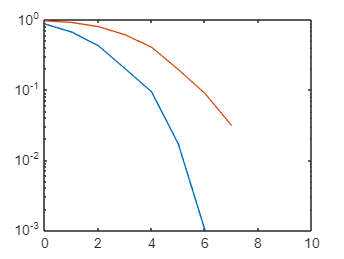

semilogy(sLog,PerrDecSoft);
hold on;
semilogy(sLog,PerrDecHard);
hold off;

Below is the output for interweaved data bits v/s normal data bits

This is done in order to reduce chances of burst error corrupting a large chunk of information

It is done so for rate 1/2 code by first sending all 1st output bit of each input and then sending 2nd output bit.

This way if some 1st bits gets corrupted then we can extract some information from remaing 2nd output bits since they were not in series otherwise both would have gotten corrupted. 

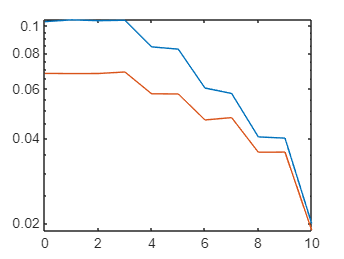

% Now we see for interweaving the data and then sending it.
noOfInput=1;
lenOfInput=50;
noOfState=8;
lenOfOutput=2;
maxV=1;
noOfBand=8;
rate=noOfInput/lenOfOutput;
sLog=linspace(0,10,11);% value of Eb/N0 in db
s=10.^(sLog/10);% value of Eb/N0 in normal scale
g=s;% value of Es/No in normal scale is 2eb/
Diagram=stateDiagram(noOfState,noOfInput);
nMax=3000;
BERSI=zeros(1,11);% Interweaved data BER for soft decesion decoding
BERSN=zeros(1,11);% Noraml data BER for soft decesion decoding
inputSet=zeros(nMax,lenOfInput-log2(noOfState));
for i=1:nMax
    inputSet(i,:)=randi([0,1],1,lenOfInput-log2(noOfState));
end
for Pow=1:11
    S=1/sqrt(g(Pow));
    for iter=1:nMax
        input=inputSet(iter,:);
        zeroPadd=zeros(1,log2(noOfState));
        input=[input,zeroPadd];
        output=[];
        prevState=zeros(1,log2(noOfState));
        for i=1:lenOfInput/noOfInput
            [out,prevState]=Encoder(input((i-1)*noOfInput+1:i*noOfInput),prevState);
            output=[output,out];
        end
        % Here we will try to seperate output bits and send them after some
        % delay
        O1=output(1:2:end);
        O2=output(2:2:end);
        outputI=[O1,O2];
        sendI=BPSKSender(outputI,maxV);
        sendN=BPSKSender(output,maxV);
        sendI=BurstErrorChannel(sendI,S);
        sendN=BurstErrorChannel(sendN,S);
        receiveI=BPSKSoftReceiver(sendI,noOfBand,maxV,S);
        receiveN=BPSKSoftReceiver(sendN,noOfBand,maxV,S);
        for i=1:length(outputI)
            receiveM(i)=mod(i,2)*receiveI(int8(i/2))+mod(i+1,2)*receiveI(int8(i/2)+lenOfInput);
        end
        decodedI=decoderSoft(receiveM,lenOfOutput,noOfState,Diagram,noOfBand,1);
        decodedN=decoderSoft(receiveN,lenOfOutput,noOfState,Diagram,noOfBand,1);
        BERSI(Pow)=BERSI(Pow)+sum(xor(input(1:end-log2(noOfState)),decodedI(1:end-log2(noOfState))));
        BERSN(Pow)=BERSN(Pow)+sum(xor(input(1:end-log2(noOfState)),decodedN(1:end-log2(noOfState))));
        % We dont need to know what the last 3 bits are since they will be 0
    end
end
BERSI=BERSI/(nMax*length(input));
BERSN=BERSN/(nMax*length(input));
semilogy(sLog,BERSI);
hold on;
semilogy(sLog,BERSN);
hold off;

Now we see in Soft decesion rather than Euclidean distance when we use manhattan distance the BER performance we get:

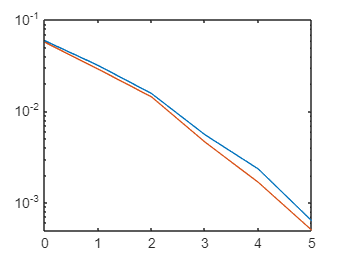

noOfInput=1;
lenOfInput=10;
noOfState=8;
lenOfOutput=2;
maxV=1;
noOfBand=8;
rate=noOfInput/lenOfOutput;
sLog=linspace(0,10,11);% value of Eb/N0 in db
s=10.^(sLog/10);% value of Eb/N0 in normal scale
g=s;% value of Es/No in normal scale is 2eb/
Diagram=stateDiagram(noOfState,noOfInput);
nMax=3000;
BERSE=zeros(1,11);% Interweaved data BER for soft decesion decoding
BERSM=zeros(1,11);% Noraml data BER for soft decesion decoding
inputSet=zeros(nMax,lenOfInput-log2(noOfState));
for i=1:nMax
    inputSet(i,:)=randi([0,1],1,lenOfInput-log2(noOfState));
end
for Pow=1:11
    S=1/sqrt(g(Pow));
    for iter=1:nMax
        input=inputSet(iter,:);
        zeroPadd=zeros(1,log2(noOfState));
        input=[input,zeroPadd];
        output=[];
        prevState=zeros(1,log2(noOfState));
        for i=1:lenOfInput/noOfInput
            [out,prevState]=Encoder(input((i-1)*noOfInput+1:i*noOfInput),prevState);
            output=[output,out];
        end
        send=BPSKSender(output,maxV);
        send=AWGNChannel(send,S);
        receive=BPSKSoftReceiver(send,noOfBand,maxV,S);
        decodedE=decoderSoft(receive,lenOfOutput,noOfState,Diagram,noOfBand,1);% 1 means Euclid Distance
        decodedM=decoderSoft(receive,lenOfOutput,noOfState,Diagram,noOfBand,0);% 0 means Manhattan Distance
        BERSE(Pow)=BERSE(Pow)+sum(xor(input(1:end-log2(noOfState)),decodedE(1:end-log2(noOfState))));
        BERSM(Pow)=BERSM(Pow)+sum(xor(input(1:end-log2(noOfState)),decodedM(1:end-log2(noOfState))));
        % We dont need to know what the last 3 bits are since they will be 0
    end
end
BERSE=BERSE/(nMax*length(input));
BERSM=BERSM/(nMax*length(input));
semilogy(sLog,BERSE);
hold on;
semilogy(sLog,BERSM);
hold off;

Analytical Approximation of BER soft and hard to the Kc=3 and 1 input 2 output encoder rate 1/2 convolution code 

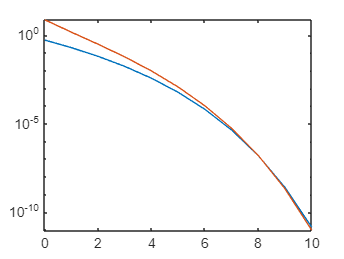

sLog=linspace(0,10,11);% value of Eb/N0 in db
s=10.^(sLog/10);% value of Eb/N0 in normal scale
g=s;% value of Es/No in normal scale
u=exp(-0.5*s);
BERS=zeros(1,11);
for i=1:11
    BERS(i)=u(i)^5/(1-u(i))^2;
end
semilogy(sLog,BERS);
hold on;

% Creating data points for q function to be evaluated at using matQfunc()
% since qFunc is in communications toolbox but we are not allwed to use it.
q=zeros(1,100000);
x=linspace(-1000,1000,100000);% Sampling points to later do a linear interpolation to get proper value.
for i=1:100000
    q(i)=matQfunc(x(i));
end

P=sqrt(2.*s);
PBF=interp1(x,q,P);
PBER=zeros(1,11);
D=zeros(1,11);
for i=1:11
    D(i)=sqrt(8*PBF(i)*(1-PBF(i)));
    PBER(i)=D(i)^5/(1-D(i))^2;
end
semilogy(sLog,PBER);
hold off;

function val=matQfunc(min)
N=100000;
nMax=10000;
dx=(nMax-min)/N;
x=linspace(min,nMax,N);
y=(1/sqrt(2*pi)).*exp(-(x.^2)/2);
Ay=sum(y);
val=Ay*dx;
end